# Eulerian Method

% Define the file path
filePath = "C:\Users\raymo\Desktop\Tremor_apparal-Raymond-2024-04-30\videos\apparelDLC_resnet50_Tremor_apparalApr30shuffle1_300000.csv";
videoPath = "C:\Users\raymo\Desktop\Tremor_VA-Raymond-2024-04-27\videos\apparel.mp4";

% Specify options for reading the file
opts = detectImportOptions(filePath);
opts.SelectedVariableNames = [2, 3]; % Reading the second and third columns
opts.DataLines = [4, Inf];  % Start reading from row 4 to the end of the file

% Read the CSV file into a table with specified options
dataTable = readtable(filePath, opts);

% Assign columns to X and Y
wrist_x = dataTable{:,1};
wrist_y = dataTable{:,2};

% Display first few rows of X and Y to verify they are loaded correctly
disp(head(wrist_x));

   1.0e+03 *

    1.1628
    1.1778
    1.1714
    1.1637
    1.1726
    2.2279
    1.1719
    1.1749



disp(head(wrist_y));

  779.9375
  780.9893
  763.3140
  738.8157
  734.7863
  819.8874
  716.2061
  715.9610



## Plot positions

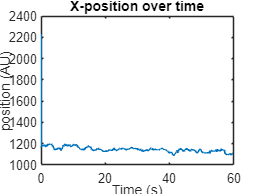

fs = 60; % sampling frequency (Hz)
t = 0:1/fs:length(wrist_x)/fs-1/fs;
figure;
plot(t,wrist_x);
title('X-position over time'); xlabel('Time (s)'); ylabel('position (AU)');

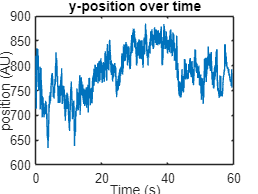


figure;
plot(t,wrist_y);
title('y-position over time'); xlabel('Time (s)'); ylabel('position (AU)');

## Kalman Filter 

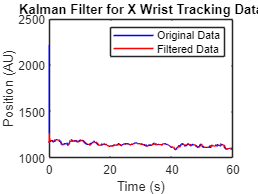

% Initialize Kalman filter parameters
A = eye(1); % State transition matrix (for almost constant position)
H = 1; % Measurement matrix (only position is measured)
Q = 0.01; % Process noise covariance (low because we assume almost constant position)
R = 1; % Measurement noise covariance (only position is measured)
xX = wrist_x(1);  % Initial state estimate for X position
xY = wrist_y(1);  % Initial state estimate for Y position
P = 0.1;  % Initial error covariance

n = length(wrist_x);  % Number of samples
filteredX = zeros(n, 1);
filteredY = zeros(n, 1);

% Kalman filtering for X data
for k = 1:n
    % Prediction
    xPred = A * xX;
    PPred = A * P * A' + Q;

    % Update
    K = PPred * H' / (H * PPred * H' + R);
    xX = xPred + K * (wrist_x(k) - H * xPred);
    P = (1 - K * H) * PPred;
    filteredX(k) = xX;
end

% Kalman filtering for Y data
for k = 1:n
    % Prediction
    xPred = A * xY;
    PPred = A * P * A' + Q;

    % Update
    K = PPred * H' / (H * PPred * H' + R);
    xY = xPred + K * (wrist_y(k) - H * xPred);
    P = (1 - K * H) * PPred;
    filteredY(k) = xY;
end

% Plot original and filtered data for X
figure;
plot(t, wrist_x, 'b', t, filteredX, 'r');
legend('Original Data', 'Filtered Data');
xlabel('Time (s)');
ylabel('Position (AU)');
title('Kalman Filter for X Wrist Tracking Data');

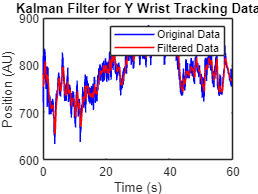


% Plot original and filtered data for Y
figure;
plot(t, wrist_y, 'b', t, filteredY, 'r');
legend('Original Data', 'Filtered Data');
xlabel('Time (s)');
ylabel('Position (AU)');
title('Kalman Filter for Y Wrist Tracking Data');

## Eulerian

% Define orientations and scales
orientations = [0, pi/4, pi/2, 3*pi/4]; % angles in radians
sigma = [1 0.5 0.25]; % standard deviation of Gaussian/scales
filter_size = 2*ceil(2*sigma)+1; % filter size

% load input video
vid = VideoReader(videoPath);
frameRate = vid.FrameRate;
numFrames = vid.NumFrames;

% Initialize complex steerable pyramid video
complex_pyramid = cell(numFrames,length(orientations),length(sigma));
gray = cell(numFrames,1);

% Specify the size of the window (adjust as needed)
window_size = [100, 100]; % [width, height]

% initialize cell array containing complex steerable filters
complex_filt = cell(length(orientations), length(sigma));

for frame = 1:numFrames
    input_frame = read(vid,frame);
    
    % Calculate the cropping window around the selected point
    crop_window = [round(filteredX(frame) - window_size(1)/2), round(filteredY(frame) - window_size(2)/2), window_size(1), window_size(2)];
    
    % Perform cropping
    cropped_image = imcrop(input_frame, crop_window);
    input_image = rgb2gray(cropped_image);
    gray{frame} = double(input_image); % grayscale cropped image
    
    for i = 1:length(orientations)
        for j = 1:length(sigma)
            % Create complex steerable filters G and H for each orientation and scale
    
            % Create a Gaussian filter
            G = fspecial('gaussian', [filter_size(j), filter_size(j)], sigma(j));
            % Compute the gradient of the Gaussian filter
            [Gx, Gy] = gradient(G);
    
            G1 = cos(orientations(i)) * Gx + sin(orientations(i)) * Gy; % Combine gradients based on orientation
            rotated_filter = imrotate(G1, -orientations(i)*180/pi, 'loose'); % Negative angle for correct orientation
    
            % Hilbert transform of Gaussian
            h = hilbert(rotated_filter);
            complex_filt{i,j} = h;

            % Convolve filter with frame
            conv_image = conv2(input_image,complex_filt{i,j},'same');
            
            % get phase only to normalize image
            conv_image = double(conv_image);
            phase = angle(conv_image);
            complex_pyramid{frame,i,j} = phase;
    
        end
    end
end

% visualize video frames
% for frame = 1:5
%     for i = 1:numel(orientations)
%         for j = 1:numel(sigma)
%             figure;
%             imagesc(mat2gray(real(complex_pyramid{frame,i,j}))); colormap gray;
%             title(['Frame: ', num2str(frame),', Orientation: ', num2str(orientations(i)), ', Scale: ', num2str(sigma(j))]);
% 
%             % Display the filters for debugging
%             % figure;
%             % subplot(1, 2, 1);
%             % imagesc(real(complex_filt{i,j})); colormap gray;
%             % title(['Real Part - Orientation: ', num2str(orientations(i)), ', Scale: ', num2str(sigma(j))]);
%             % 
%             % subplot(1, 2, 2);
%             % imagesc(imag(complex_filt{i,j})); colormap gray;
%             % title(['Imaginary Part - Orientation: ', num2str(orientations(i)), ', Scale: ', num2str(sigma(j))]);
%         end
%     end
%         figure;
%         imagesc(mat2gray(real(gray{frame}))); colormap gray;
%         title(['Frame: ', num2str(frame),', Grayscale']);
% end


## Filter & PSD

% Design the Butterworth band-pass filter
low_cut = 2; % lower cut-off frequency (Hz)
high_cut = 14; % higher cut-off frequency (Hz)
[b, a] = butter(2, [low_cut/(frameRate/2) high_cut/(frameRate/2)], 'bandpass');
freq = []; % frequencies vector for PSD

% Window parameters
n = numFrames; % Length of each segment for the Welch method
overlap = floor(0.4*n); % 40% overlap
alpha = frameRate / (n - 1); % Alpha for the Tukey window
window = tukeywin(n, alpha);

% Initialize cell array to store PSDs
numOrientations = numel(orientations);
numScales = numel(sigma);
psd_f = cell(numOrientations, numScales); % Each cell will store PSDs for one configuration

% Iterate over each orientation and scale
for i = 1:numOrientations
    for j = 1:numScales
        [h, w] = size(complex_pyramid{1, i, j}); % assuming size is consistent across frames
        % pixel_psd = zeros(h, w);
        % frame_psd = zeros(numFrames, 1);
        
        % Initialize sum storage for PSD values
        summed_psd = [];

        % Process each pixel location
        for height = 1:h
            for width = 1:w
                pixel_data = zeros(numFrames, 1);
                
                % Extract data for this pixel across all frames
                for frame = 1:numFrames
                    pixel_data(frame) = complex_pyramid{frame, i, j}(height, width);
                end
                
                % filter
                filtered_data = filter(b, a, pixel_data);

                % Calculate PSD using Welch's method
                [psd, f] = pwelch(filtered_data, window, overlap, [], frameRate, 'onesided');
                
                % Initialize variables on the first run
                if isempty(summed_psd)
                    freq = f; % Set frequency vector
                    numFreqBins = length(psd); % Get the number of frequency bins
                    summed_psd = psd; % Initialize summed_psd with the correct length
                else
                    % accumulate the PSD values
                    summed_psd = summed_psd + psd;
                end
            end
        end
        
        % Average the accumulated PSD values for all pixels
        psd_f{i, j} = summed_psd / (h * w);
    end
end

% repeat with 13th channel, grayscale crop
[h, w] = size(gray{1}); 

% Initialize sum storage for PSD values
summed_psd = [];

% Process each pixel location
for height = 1:h
    for width = 1:w
        pixel_data = zeros(numFrames, 1);
        
        % Extract data for this pixel across all frames
        for frame = 1:numFrames
            pixel_data(frame) = gray{frame}(height, width);
        end
        
        % filter
        filtered_data = filter(b, a, pixel_data);

        % Calculate PSD using Welch's method
        [psd, f] = pwelch(filtered_data, window, overlap, [], frameRate, 'onesided');
        
        % Initialize variables on the first run
        if isempty(summed_psd)
            summed_psd = psd; % Initialize summed_psd with the correct length
        else
            % accumulate the PSD values
            summed_psd = summed_psd + psd;
        end
    end
end

% Average the accumulated PSD values for all pixels
psd_gray = summed_psd / (h * w);

## Plot & Score

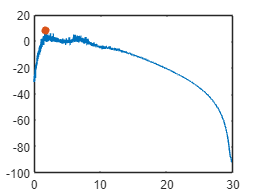

1.787 Hz


k = 3; % Adjustable parameter
scores_c = zeros(13, 1);
idx = 1; % index for scores array

% flatten PSD channels array and add the grayscale channel
psd_f_new = cell(13, 1);

for i = 1:numOrientations
    for j = 1:numScales
        k = (i - 1) * numScales + j;  % Calculate the new index
        psd_f_new{k} = psd_f{i, j};   % Assign the cell content
    end
end
psd_f_new{13} = psd_gray;

for channel = 1:13
    mu_p = mean(psd_f_new{channel});
    sigma_p = std(psd_f_new{channel});
    score = max(psd_f_new{channel} - mu_p - (k * sigma_p)) / (numFrames/n);
    scores_c(channel) = score; % Store the maximum score for comparison
end

sumArray = zeros(size(psd_f_new{1}));

% Sum across all cells
for k = 1:numel(psd_f_new)
    sumArray = sumArray + psd_f_new{k};
end


[~, m_channel] = max(scores_c); % Accessing the PSD of the best channel
figure;
plot(freq,10*log10(psd_f_new{m_channel}));  % Plot in decibels (dB)
hold on
[maxValue, maxIndex] = max(psd_f_new{m_channel}); % plot max value
amplitude = 10*log10(maxValue); % amplitude of dominant tremor frequency
scatter(freq(maxIndex),10*log10(maxValue),'filled');
disp([num2str(freq(maxIndex)), ' Hz'])

6.2035 Hz


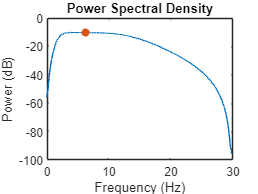


xlabel('Frequency (Hz)');
ylabel('Power (dB)');
title('Power Spectral Density');
hold off

xlabel('Frequency (Hz)');
ylabel('Power (dB)');
title('Power Spectral Density');
hold off

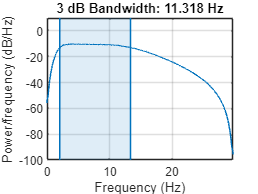

% 3-dB (half power) bandwidth 
[bandwidth, freq_lower, freq_higher, band_power] = powerbw(psd_f_new{m_channel}, freq);
figure; 
powerbw(psd_f_new{m_channel}, freq);

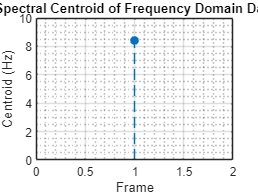


% spectral centroid
spectral_centroid = spectralCentroid(psd_f_new{m_channel}, freq);
figure;
spectralCentroid(psd_f_new{m_channel}, freq);
title("Spectral Centroid of Frequency Domain Data")

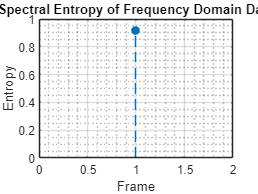


% Calculate spectral entropy
spectral_entropy = spectralEntropy(psd_f_new{m_channel}, freq);
figure;
spectralEntropy(psd_f_new{m_channel}, freq);
title("Spectral Entropy of Frequency Domain Data")


disp(['Dominant Frequency: ', num2str(freq(maxIndex)), ' Hz'])

Dominant Frequency: 6.2035 Hz


disp(['Amplitude: ', num2str(amplitude), ' dB/Hz'])

Amplitude: -9.9684 dB/Hz


disp(['Bandwidth: ', num2str(bandwidth), ' Hz'])

Bandwidth: 11.3176 Hz


disp(['Lower Bound: ', num2str(freq_lower), ' Hz'])

Lower Bound: 2.0301 Hz


disp(['Upper Bound: ', num2str(freq_higher), ' Hz'])

Upper Bound: 13.3477 Hz


disp(['Percent Power Stored in Bandwidth: ', num2str(band_power), ' dB']);

Percent Power Stored in Bandwidth: 0.94053 dB


disp(['Spectral Centroid: ', num2str(spectral_centroid), ' Hz']);

Spectral Centroid: 8.4144 Hz


disp(['Spectral Entropy: ', num2str(spectral_entropy)]);

Spectral Entropy: 0.91962


Elapsed time is 676.433526 seconds.
